# Factorización *PCA y NMF*

## Importación y limpiado de la imagen + detección de *blobs*

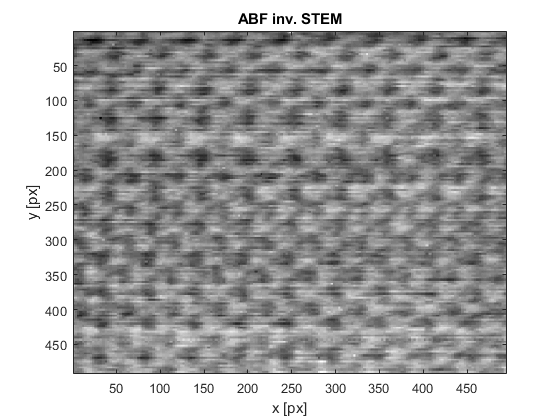

clc, clear, close all

% Leemos el mapa de bits que sale del microscopio
Ir = imread('../data/ABF_DAT.png');
Ir = double(rgb2gray(Ir));
Ir = Ir/max(max(Ir));

% Dibujamos original
figure(), clf;
imagesc(Ir), colormap gray;
title("ABF inv. STEM")
xlabel("x [px]"), ylabel("y [px]")

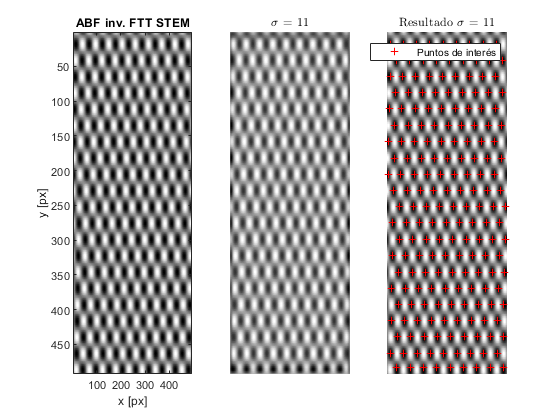


% Extraigo la periodicidad por FFT
thresh = 0.03;
Yt = fft2(Ir);
Max = max(max(abs(Yt)));
ind = abs(Yt) > thresh*Max;
Atlow = single(Yt .* ind);
Ilow = double(ifft2(Atlow));

% Llevo a 0 y renormalizo
I = Ilow - min(min(Ilow));
I = I/max(max(abs(I)));

% Detección de blobs por NLoG (pesado de compilar)
sgm_list = 11;
[x,y] = blobDetector(I,sgm_list,0.04,0);

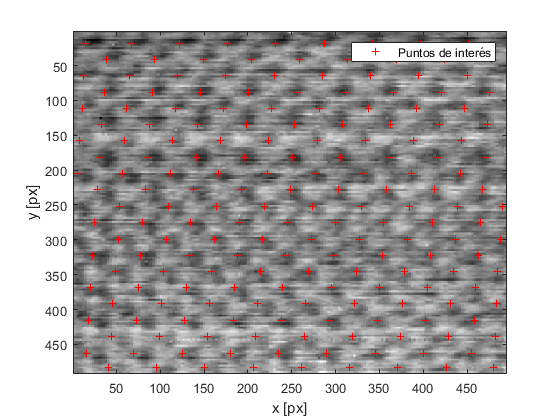


% Visualizamos lo puntos de interés en la imagen real
I = Ir;

figure()
imagesc(I), colormap gray, hold on;
plot(x,y,'r+', 'MarkerSize', 5, 'LineWidth', 0.1);
legend("Puntos de interés")
xlabel("x [px]"), ylabel("y [px]")

## Extracción de los parches de información

Generamos la Figura 8 para visualizar cómo se va a construir la matriz $X$:

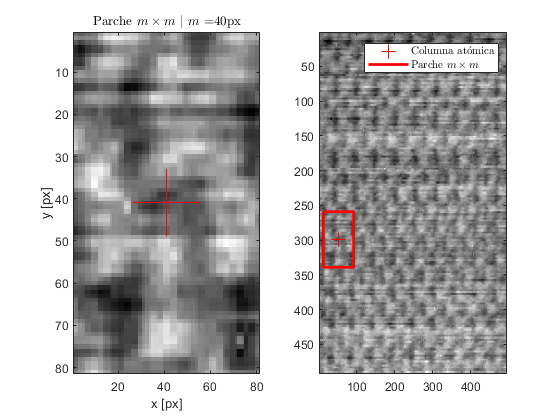

m = 40; % Distacia respecto al blob a cada lado
c = 20; % Elegimos una columna que cumpla las condiciones

figure(1), clf;

% Extraemos el parche seleccionado
I_patch = I(y(c)-m : y(c)+m ,x(c)-m : x(c)+m);
                                               
subplot(1,2,1)
imagesc(I_patch), colormap gray, hold on;
plot(m+1,m+1,'r+', 'MarkerSize', 50, 'LineWidth', 0.7)
title("Parche $m\times m$ $|$ $m = $" + num2str(m) + "px",'interpreter','latex')
xlabel("x [px]"), ylabel("y [px]")

% Dibujamos localización del parche en la imagen
x1 = x(c)-m; y1 = y(c)-m;
x2 = x(c)-m; y2 = y(c)+m;
x3 = x(c)+m; y3 = y(c)+m;
x4 = x(c)+m; y4 = y(c)-m;

subplot(1,2,2)
imagesc(I), colormap gray, hold on;
plot(x(c),y(c),'r+', 'MarkerSize', 10, 'LineWidth', 0.7)
plot([x1 x2 x3 x4 x1],[y1 y2 y3 y4 y1], "-r", "LineWidth",2)
legend("Columna at\'omica", "Parche $m\times m$",'interpreter', 'latex')

Una vez mostrado el proceso, generamos el tensor de información $T$ para posteriormente aplanarlo y transformarlo en la matriz $X$ que procesaremos por los distintos métodos de factorización matricial:

m = 40; % Distacia respecto al blob a cada lado

% Contabilizamos cuántos parches vamos a generar para inicializar T y X
patchs = 0;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < (size(I,2) - m) && y(i) < (size(I,1) - m))
        patchs = patchs + 1;
    end
end
T = zeros(2*m+1 ,2*m+1, patchs);
X = zeros(patchs, (2*m+1)^2);

% Extraemos todos los parches
patch = 1;
for i = 1:length(x)
    if (x(i) > m && y(i) > m) && (x(i) < size(I,2) - m && y(i) < size(I,1) - m)
        I_patch = I(y(i)-m : y(i)+m ,x(i)-m : x(i)+m);
        T(:,:,patch) = I_patch;
        patch = patch + 1;
    end
end

% Aplanamos el tensor
X = reshape(T, (2*m+1)^2, patchs)';
X_train = X;

## Descomposición PCA $(X = UV')$

% Hacemos uso del algoritmo implementado en MATLAB
% (requiere "Statistics and Machine Learning Toolbox")
[V,U,s2] = pca(X_train);

% Nos quedamos con los dos primeros coeficientes porque son los que tienen
% una mayor varianza (s2)
disp("Varianza de 4 primeras PC")

Varianza de 4 primeras PC


disp(s2(1:4))

   12.4452
    8.0594
    6.2761
    5.3369




% Visualizamos las dos componentes principales escogidas
U = U/max(max(abs(U)));

figure(4), clf;
colormap gray; colorbar

subplot(4,4,[1 5 9]);
plot(U(:,1),U(:,2),".b"), grid on, hold on;
xlim([-1.2 1.2]), ylim([-1.2 1.2])
xlabel("Primera componente principal")
ylabel("Segunda componente principal")
title("PCA: Primeras dos componentes")

%biplot(V(:,1:2),'scores',score(:,1:2)), hold on;

% Mostramos la imagen reconstruida a partir de las
% primeras componentes principales
X_ = U(:,1:3)*V(:,1:3)';
X_ = X_/max(max(abs(X_)));
I_ = reshape(X_(c,:),2*m+1,2*m+1);
subplot(4,4,2);
imagesc(I_)
title("\textbf{PCA }$| \; X = U \times V$","Interpreter","latex")

% Mostramos las componentes por separado
I_1 = reshape(V(:,1),2*m+1,2*m+1);
subplot(4,4,6);
imagesc(I_1), colorbar, axis off
title("$V_p$ $|$ p = 1","Interpreter","latex")

I_2 = reshape(V(:,2),2*m+1,2*m+1);
subplot(4,4,10);
imagesc(I_2), colorbar, axis off
title("p = 2","Interpreter","latex")

I_3 = reshape(V(:,3),2*m+1,2*m+1);
subplot(4,4,14);
imagesc(I_3), colorbar
title("p = 3","Interpreter","latex")
xlabel("x [px]"), ylabel("y [px]")


## Descomposición NMF

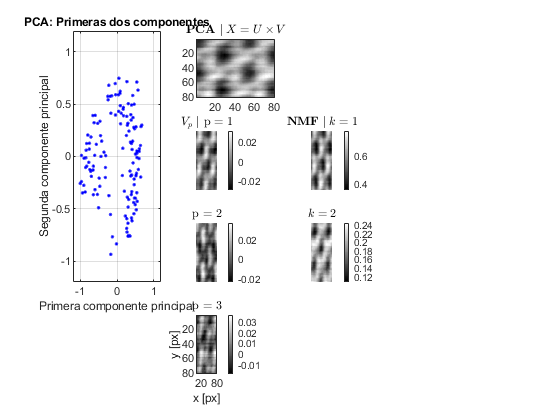

% Realizamos la factorización NMF
[Un,Vn] = nnmf(X,2);

% Mostramos las dos componentes
X_1 = Un(:,1)*Vn(1,:);
X_1 = X_1/max(max(abs(X_1)));
I_1 = reshape(X_1(c,:),2*m+1,2*m+1);
subplot(4,4,7);
imagesc(I_1), colorbar, axis off
title("\textbf{NMF }$| \; k = 1$","Interpreter","latex")

X_2 = Un(:,2)*Vn(2,:);
X_2 = X_2/max(max(abs(X_2)));
I_2 = reshape(X_2(c,:),2*m+1,2*m+1);
subplot(4,4,11);
imagesc(I_2), colorbar, axis off
title("$k = 2$","Interpreter","latex")

## Seleccionamos los parches 

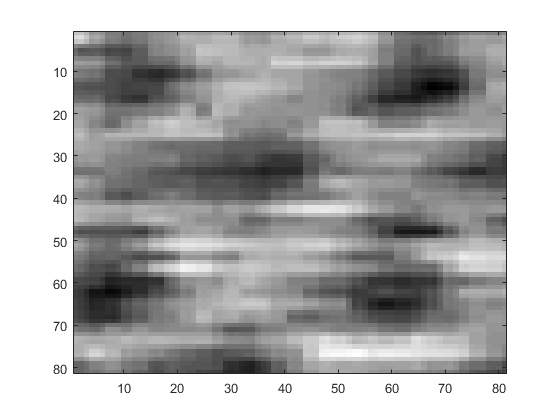

% Buscamos todos los máximos locales y los marcamos
ids = [find(U(:,1) < -0.25)];

% Los guardamos limpios y con ruido
X_clean = zeros(length(ids),(2*m+1)^2);
X_noisy = X_clean;

for i = 1:length(ids)
    X_clean(i,:) = X_train(ids(i),:);
    X_noisy(i,:) = X_clean(i,:) + 0.5*randn(size(X_clean(i,:)));
    X_noisy(i,:) = X_noisy(i,:) - min(min(X_noisy(i,:)));
    X_noisy(i,:) = X_noisy(i,:)/max(max(X_noisy(i,:)));
    imwrite(uint8(reshape(X_clean(i,:),2*m+1,2*m+1)*255), "clean_patches/dat_"+ num2str(i) +".png")
    imwrite(uint8(reshape(X_noisy(i,:),2*m+1,2*m+1)*255), "noisy_patches/dat_"+ num2str(i) +".png")
end

writematrix(X_clean,"clean_patches/clean_stack.csv")
writematrix(X_noisy,"noisy_patches/noisy_stack.csv")

figure() 
colormap gray
imagesc(reshape(X_clean(ids(10),:),2*m+1,2*m+1))